## [Decision Tree](https://apmonitor.com/pds/index.php/Main/DecisionTree)

A decision tree classifier is a type of machine learning algorithm that is used to predict the class or label of an input data point by making decisions based on the values of the features of the data.

Given attribute data (features) together with its classes (labels), a decision tree produces a sequence of rules that can be used to classify the data. The algorithm works by recursively partitioning the training data into smaller subsets based on the values of the features, until each subset contains only data points belonging to a single class. The resulting tree structure is then used to make predictions on new data points by traversing the tree and making decisions at each node based on the values of the input data point's features.

**Advantages:** Decision Tree is simple to understand and visualise, requires little data preparation, and can handle both numerical and categorical data.

**Disadvantages:** Decision tree can create complex trees that do not generalise well, and decision trees can be unstable because small variations in the data might result in a completely different tree being generated.

In this example, we first create a decision tree classifier using the Decision Tree Classifier. Then, we train the model on the training data using the fit method. Finally, we use the trained model to make predictions on the test set programmatically with the [*predict*](https://www.mathworks.com/help/stats/linearmodel.predict.html) function.

**Optical Character Recognition with Decision Tree Example**

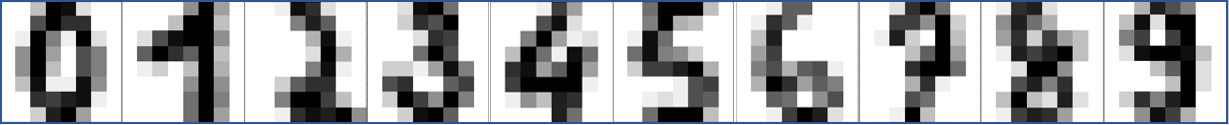

Optical character recognition (OCR) is the process of extracting text from images or scanned documents. OCR algorithms are typically based on machine learning models that are trained on large datasets of images containing text. Here is an example of OCR using a decision tree classifier.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

### Import and Organize the Data

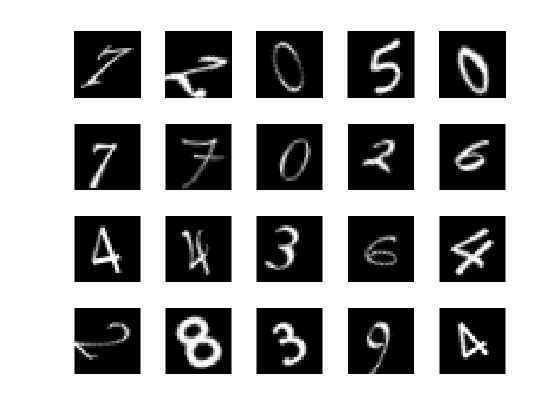

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = cell(n_samples, 1);
for i = 1:n_samples
    [X_data{i}] = deal(reshape(readimage(imds,i)',[1,28*28]));
end
X_data = cell2mat(X_data);

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

### Train and Evaluate the Model

% Create fit
classifier = fitctree(array2table(im2double(X_Train)),Y_Train);

% Evaluate the model performance on the test set
ypred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(ypred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.75


In this example, we first load the digits dataset, which contains images of handwritten digits. Then, we create a decision tree classifier using the Decision Tree Classifier class. Next, we train the model on the digits dataset. Finally, we use the trained model to make predictions on new images to generate an accuracy score.

Note that this is just a simple example of OCR using a decision tree classifier, and many other more advanced OCR algorithms exist. Decision tree classifiers may not be the most effective model for OCR tasks, as they are not well-suited to high-dimensional datasets like images.

#### Interactive Method

Use the [Classification Learner App](https://www.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html) to train a classification tree and predict responses to data. 

### Test Individual Predictions

This is an example that shows a number from the test set and evaluates it with the Decision Tree Classifier.

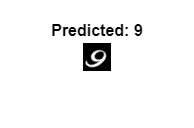

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);

% Get the prediction
reshape(readimage(imds,n)',[1,28*28]);
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));

% Display the image with the prediction
figure;
imshow(imds.Files{n})
titleText = "Predicted: " + string(yp);
title(titleText, 'FontSize', 12)